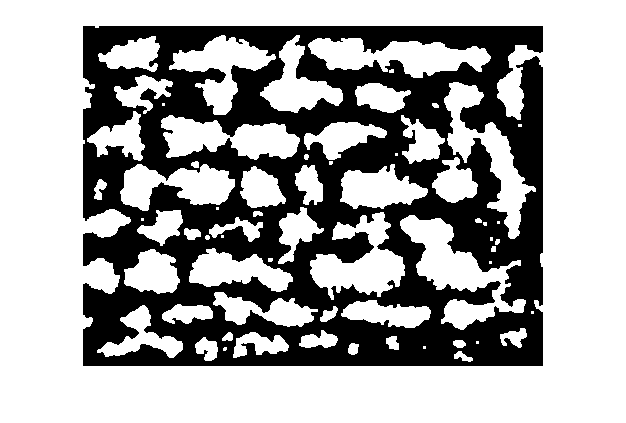

%if (half_yes) &&  not(isempty(method_name))
%    if(strcmp(method_name, 'nearest'))
%        img=imresize(img,2,'nearest');
%    elseif(strcmp(method_name, 'bilinear'))
%        img=imresize(img,2,'bilinear');
%    elseif(strcmp(method_name, 'bicubic'))
%        img=imresize(img,2,'bicubic');
%    elseif(strcmp(method_name, 'lanczos2'))
%        img=imresize(img,2,'lanczos2');
%    elseif(strcmp(method_name, 'lanczos3'))
%        img=imresize(img,2,'lanczos3');
%    end
%end
inverted = 1;
img = imread("Immagini_nuove\F1_IR000650_cropped.png_SK-w=20_r=2.jpg");
%img = rgb2gray(img);

%filtro mediano
img = medfilt2(img);

%incremento contrasto immagine
max_value=max(img(:));
min_value=min(img(:));
img = imadjust(img, [min_value/255 max_value/255], [0.0 1.0]);

img=not(adaptivethreshold(img,floor(size(img,1)/6), 0.0, 0));
%img=not(imbinarize(img,"adaptive"));

%rimozione buchi
[N, M] = size(img);
img_tmp = zeros(N+4, M+4);
img_tmp(3:N+2,3:M+2) = img;
img_tmp_filled = imfill(img_tmp, 'holes');
img = img_tmp_filled(3:N+2, 3:M+2);

if (inverted)
    %erosione
    img=imerode(img, strel('square',3));
    %dilatazione
    img=imdilate(img,strel('square',3));
else
    %dilatazione
    img=imdilate(img,strel('square',3));
    %erosione
    img=imerode(img, strel('square',3));
end

imshow(img)

result=img;

%Numero totale di pixel nell'immagine
total_pixel = size(img,1) * size(img,2)

%Pixel bianchi nell'immagine binarizzata
pixel_bianchi = nnz(img)

%Pixel neri
pixel_neri = sum(img(:)==0)

total_pixel - pixel_bianchi

O=imread("F\F1_IR000650.bmp");
SK=imread("half_F_SK\half_F1_IR000650.bmp_SK-w=20_r=2.bmp");
img=imread("half_F\half_F1_IR000650.bmp");
NN=imresize(img,2,'nearest');
Bil=imresize(img,2,'bilinear');
Bic=imresize(img,2,'bicubic');
L3=imresize(img,2,'lanczos3');
L2=imresize(img,2,'lanczos2');
psnr(SK,O)

ans = 30.3761

psnr(NN,O)

ans = 31.1875

psnr(L3,O)

ans = 32.2854

psnr(L2,O)

ans = 32.5345

psnr(Bic,O)

ans = 32.5548

psnr(Bil,O)

ans = 32.8175

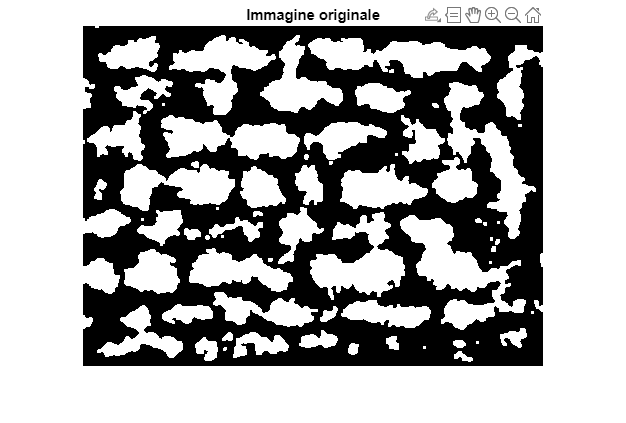

% Calcolo delle componenti connesse
cc = bwconncomp(img);

% Numero totale di componenti connesse
numeroComponentiConnesse = cc.NumObjects;
%disp(['Numero di componenti connesse: ' num2str(numeroComponentiConnesse)]);
% Etichettatura delle componenti connesse
etichette = labelmatrix(cc);

% Conversione dell'immagine etichettata in un'immagine colorata
immagineColorata = label2rgb(etichette);

% Visualizzazione dell'immagine originale e dell'immagine con le componenti connesse colorate
imshow(img);
title('Immagine originale');

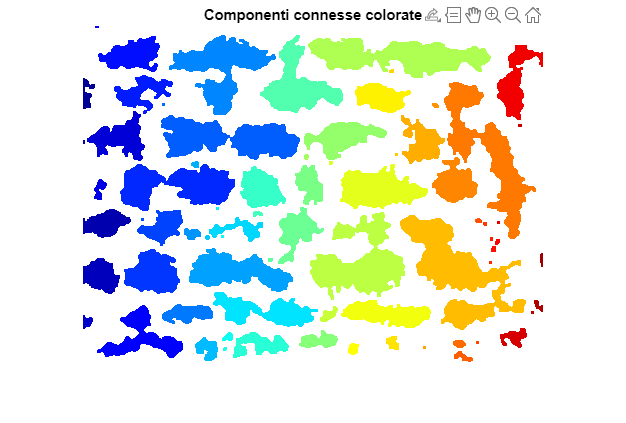


imshow(immagineColorata);
title('Componenti connesse colorate');

%DA MODIFICARE RISPETTO AL PATH DELLA CARTELLA DA USARE!!
path="";

%DA MODIFICARE RISPETTO ALLA GRANDEZZA DELLE IMMAGINI NON DIMEZZATE
img_size=460;
files = dir(path + '*.png');
    for file = files'
        img = imread(path + file.name);
        if (size(img, 1) < img_size)
            method_names = {'nearest', 'bilinear', 'bicubic', 'lanczos2', 'lanczos3'};
            for i = 1:5
                result = phase_separation(img, false, true, method_names(i));
                name = file.name(1:end-4);
                name = path + name + "_phase_separation_" + method_names(i) + ".png";
                imwrite(result, name);
                name = file.name(1:end-4);
                % Calcolo delle componenti connesse
                cc = bwconncomp(result);
                % Etichettatura delle componenti connesse
                etichette = labelmatrix(cc);
                name = path + name + "_phase_separation_" + method_names(i) + "separazione_fasi.png";
                % Conversione dell'immagine etichettata in un'immagine colorata
                immagineColorata = label2rgb(etichette);
                imwrite(immagineColorata, name);
            end
        else
            result = phase_separation(img, false);
            name = file.name(1:end-4);
            name = path + name + "_phase_separation.png";
            imwrite(result, name);
            name = file.name(1:end-4);
            % Calcolo delle componenti connesse
            cc = bwconncomp(result);
            % Etichettatura delle componenti connesse
            etichette = labelmatrix(cc);
            name = path + name + "_phase_separation_" + "separazione_fasi.png";
            % Conversione dell'immagine etichettata in un'immagine colorata
            immagineColorata = label2rgb(etichette);
            imwrite(immagineColorata, name);
        end
    end

Error using imadjust>validateLowHigh
IMADJUST: LOW_IN must be less than HIGH_IN.

Error in imadjust (line 107)
validateLowHigh(lowIn,highIn,lowOut,highOut);

Error in phase_separation (<a href="matlab: opentoline('C:\Users\nicolò\Desktop\LaboratorioVulnerabilitaSismica\lab_vulnerabilita_sismica\project\phase_separation.m',41,0)">line 41</